**Load the data. **This data has been recorded, registered, masked (vasculature and non-neural pixels), computed as change in fluorescence over time (e.g. DFF) and spatially binned to 68 x 68 pixels. This is a ~5.25 minute recording. DFF was computed using a 10 second rolling mean to approximate baseline neural activity. This example data is not corrected for possible hemodynamic contributions. 

%make sure entire fpCNMF directory is added to our path.
load('MAIN\widefield small data.mat','mydata')
gp = 'genparamss'; %parameter class handle to pass through functions
%nan out pixels with no variance
dff = mydata(1:171,:,:);
dff = reshape(dff,[171*171,size(dff,3)]);
dff(nanvar(dff,[],2)<=eps,:)=NaN;
dff = reshape(dff,[171,171,size(dff,2)]);

%Visualize the data.
%figure; histogram(dff(dff~=0)); title('Distribution of dff'); xlabel('DFF'); ylabel('Count');
%figure; for i = 1500:1520; imagesc(dff(:,:,i),[-0.1 0.1]); axis off; axis square; title(sprintf('frame %d',i)); colorbar; pause(0.01); end

**Deconvolve Data and Split Into Train and Test Chunks**. Deconvolution serves two purposes. First, it better estimates the underlying neural dynamics. Second, removing the temporal smoothing of GCaMP6f helps isolate patterns of neural activity across the cortex and improves the ability of seqNMF to discover spatiotemporal motifs. Previously, we isolated this activity using filtering and thresholding (that functionality is still included); deconvolution performs the same function while minimizing data loss. Train and test chunks allow us to internally cross validate motifs on withheld data from the same recording. Fitting motifs on a shorter chunk of time also improves seqNMF performance - as the multiplicative update algorithm performs poorly when the dataset is too large (CITE Ganguli's Paper). 

[~, nanpxs, data_train, data_test] = ProcessAndSplitData(dff,[],gp); %patience.... takes a few min


	Performing a Lucy-Goosey Deconvolution (Lucy-Richardson)

	Performing full normalization to 100 value

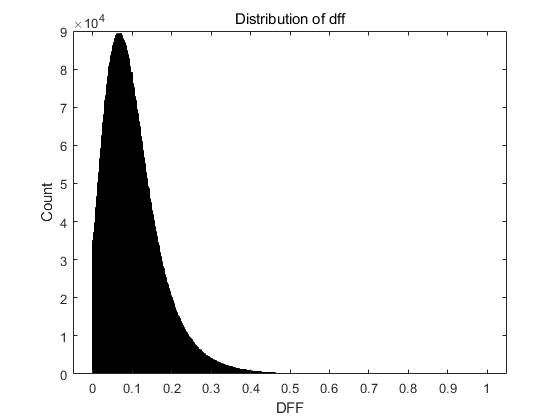

%I added a bunch of normalization options. Haven't explored all of these in great detail,
% but wanted to added them in case as different data structures may warrant different methods of normalization.

%Visualize the data.
data_train_stack = conditionDffMat(data_train',nanpxs);
figure; histogram(data_train_stack(data_train_stack~=0)); title('Distribution of dff'); xlabel('DFF'); ylabel('Count'); %

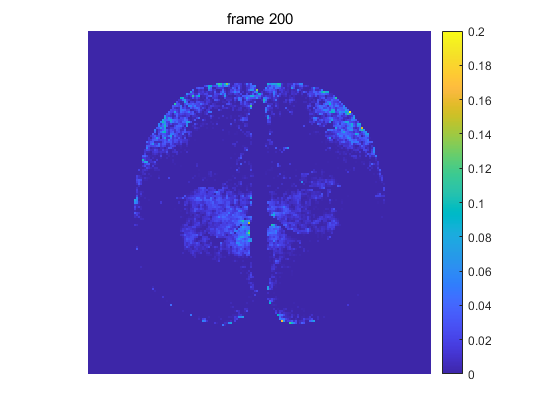

figure; for i = 1:200; imagesc(data_train_stack(:,:,i),[0 0.2]); axis off; axis square; title(sprintf('frame %d',i)); colorbar; pause(0.01); end

**Fit Motifs. **The fpCNMF  function is just a parred down (sped up) version of the original seqNMF code tailored to my own experimental questions and still in development (e.g. trying different update algorithms). I would recomend that in your data, you start with using the original seqNMF toolbox as their toolbox is peer-reviewed, beautifully commented, and includes additionally functionality. I cannot guarantee the functionality of any of my functions that are in development. 

%for reproducibility
rng('default');
opts = loadobj(feval(gp));

%optionally sweep lambda (takes ~15 min). Should produce a result ~lambda =0.0077
% opts.lambda = 0.0077; %comment out to sweep
% if numel(opts.lambda)>1
%     if opts.verbose; fprintf('\nFitting Lambda'); end
%     lambda = FitLambda(data_train,[],opts,1);
% else
%     lambda = opts.lambda;
% end
lambda = 0.0077;
%Fit Motifs To Training Data And Collect Statistics
W_temp = cell(1,opts.repeat_fits);
H_temp = cell(1,opts.repeat_fits);
stats_train_temp =cell(1,opts.repeat_fits);
for cur_fit = 1:opts.repeat_fits %fit multiple times due to random initialization. Each iteration takes ~5min
    if opts.verbose; fprintf('\nFitting Training Data Round %d of %d',cur_fit,opts.repeat_fits); end
    [W_temp{cur_fit},H_temp{cur_fit},stats_train_temp{cur_fit}] = fpCNMF(data_train,'L',opts.L,'K',opts.K,'non_penalized_iter',...
        opts.non_penalized_iter,'penalized_iter',opts.penalized_iter,...
        'speed','fast','verbose',opts.verbose,'lambda',lambda,...
        'ortho_H',opts.ortho_H,'w_update_iter',opts.w_update_iter,...
        'sparse_H',opts.sparse_H);
    %Remove Empty Motifs
    [W_temp{cur_fit},H_temp{cur_fit}] = RemoveEmptyMotifs(W_temp{cur_fit},H_temp{cur_fit});
end


Fitting Training Data Round 1 of 3


	Zoom zoom! Speediness activated! Only final statistics computed



Fitting Training Data Round 2 of 3


	Zoom zoom! Speediness activated! Only final statistics computed



Fitting Training Data Round 3 of 3


	Zoom zoom! Speediness activated! Only final statistics computed


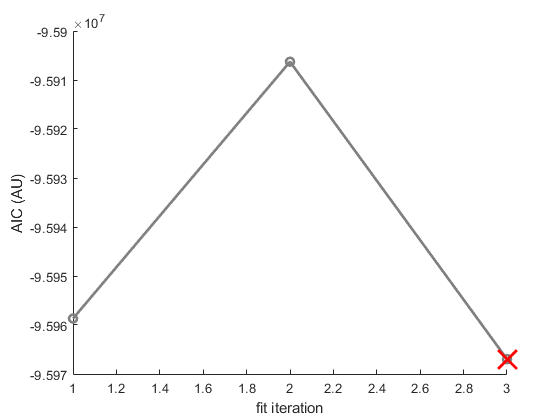

%choose best fit
idx = InternallyValidateWs(data_train,W_temp,H_temp,'AIC',1);

W = W_temp{idx}; H = H_temp{idx}; stats_train = stats_train_temp{idx};

%reorder by decreasing explained variance
[~,idx] = sort(stats_train.loadings{:},'descend')

idx =      7     6    15    16    11    14    12    19     4     2    13     3    10    18    20     8    17    21     1     5     9


W = W(:,idx,:); H = H(idx,:);
stats_train.lambda = lambda;

**Visualize Motifs and Associated Statistics. **There is  a collection of fun measures in the stats_train structure. Let's take a look at few of them. Also let's look at the motifs! 

% visualize the results of the stats_tain
fprintf('\nNumber of Motifs: %d', stats_train.n_motifs)


Number of Motifs: 21

fprintf('\nPercent Variance Explained : %0.2g%%', stats_train.pev*100)


Percent Variance Explained : 84%

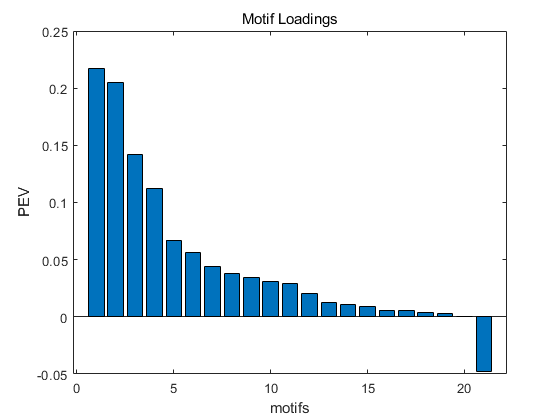


%plot the relative pev of each motif
loadings = [stats_train.loadings{:}];
figure; bar(loadings(idx)); xlabel('motifs'); ylabel('PEV'); title('Motif Loadings')

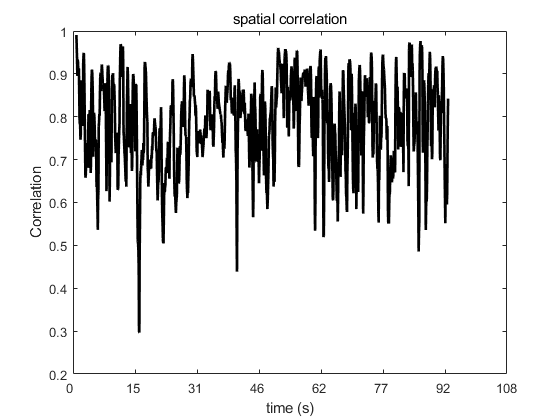


%and the spatial correlation per frame
figure; plot(stats_train.rho_frame,'linewidth',2,'color','k'); title('spatial correlation')
ylabel('Correlation'); set(gca,'xticklabel',round(get(gca,'xtick')/13,0)); xlabel('time (s)');

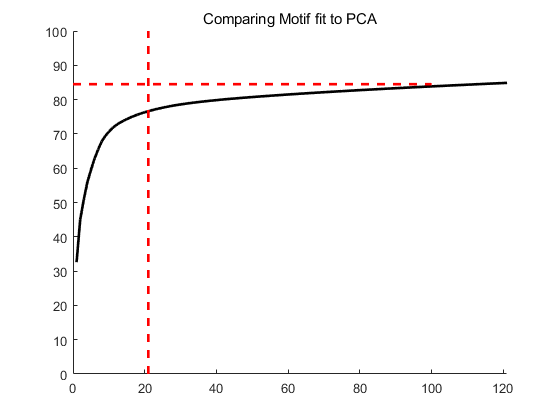


%for comparison, let's see how well PCA captures the variance in this dataset
[~, score, ~, ~, explained, ~] = pca(data_test);
figure; hold on; plot(cumsum(explained),'color','k','linewidth',2);
plot([0 100],[stats_train.pev*100,stats_train.pev*100],'linestyle','--','color','r','linewidth',2);
plot([stats_train.n_motifs,stats_train.n_motifs],[0 100],'linestyle','--','color','r','linewidth',2);
set(gca,'xlim',[0 100]); title('Comparing Motif fit to PCA')

%visualize some of the PCs as a gutcheck. Sometimes deconovlution can cause individual pixels to dominate variance.
% If so, you may want to turn on the gp.w_pc_denoise option during processing
temp = conditionDffMat(score',nanpxs);
temp = SpatialGaussian(temp,[1 1],'sigma'); %smooth for visualization
tiledlayout(3,3);

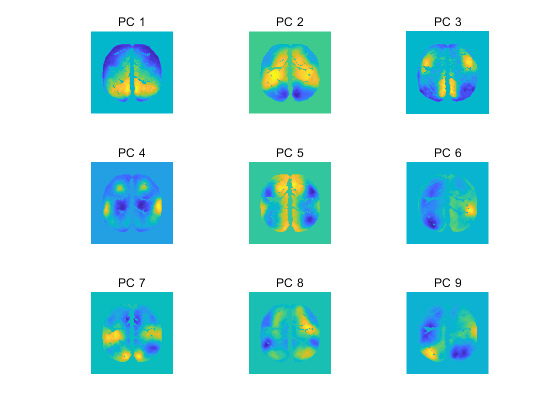

for i = 1:9; nexttile; imagesc(temp(:,:,i)); title(sprintf('PC %d',i));  axis square; axis off; end

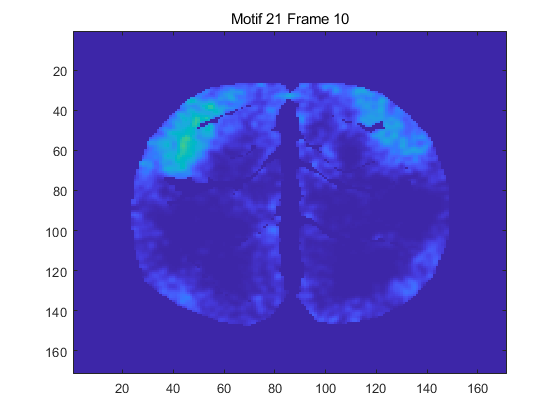


%let's visualize the motifs.
for i = 1:stats_train.n_motifs name(i)="temp"+i+".mat"; end
figure;
for i = 1:stats_train.n_motifs
    temp = conditionDffMat(squeeze(W(:,i,:))',nanpxs);
    %smooth for visualization
    temp = SpatialGaussian(temp,[1 1],'sigma');
    for j = 1:size(W,3)
        cvals = prctile(temp(:),99.9);
        imagesc(temp(:,:,j),[0 cvals]); title(sprintf('Motif %d Frame %d',i,j))
        F((i-1)*10+j)=getframe;
        pause(0.1);
    end
    tempname=char(name(i));
    %save motifs
    %save(tempname,'temp');
    pause(1); %in between motifs
end

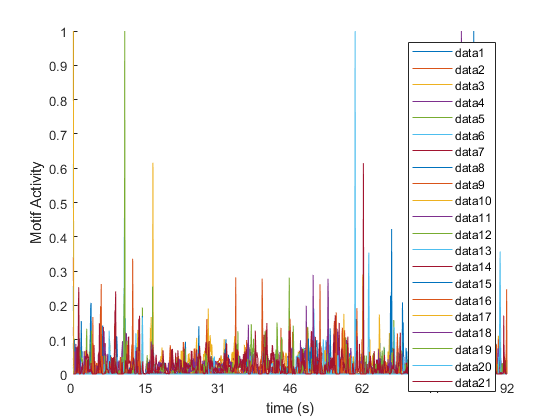

%make a video
writerObj = VideoWriter('video.avi');
open(writerObj);
writeVideo(writerObj, F)
close(writerObj);
%Plot the motif temporal weightings. You'll see that some motifs occur multiple times, others just once.
% In general, spontaneous activity is relatively sparse
figure; hold on; plot(H'); legend; ylabel('Motif Activity'); set(gca,'xticklabel',round(get(gca,'xtick')/13,0)); xlabel('time (s)');

**Cross-Validate Motifs on Withheld Data. **How well do our motifs explain withheld data from the same session? 

%Cross-validate to testing data by only fitting temporal weightings
if opts.verbose; fprintf('\nFitting Testing Data'); end


Fitting Testing Data

[~,~,stats_test] = fpCNMF(data_test,'non_penalized_iter',...
    opts.non_penalized_iter,'penalized_iter',100,...
    'speed','fast','verbose',0,'lambda',lambda,'w_update_iter',0,...
    'ortho_H',opts.ortho_H,'W',W,'sparse_H',opts.sparse_H);

fprintf('\nPercent Variance Explained : %0.2g%%', stats_test.pev*100)


Percent Variance Explained : 77%

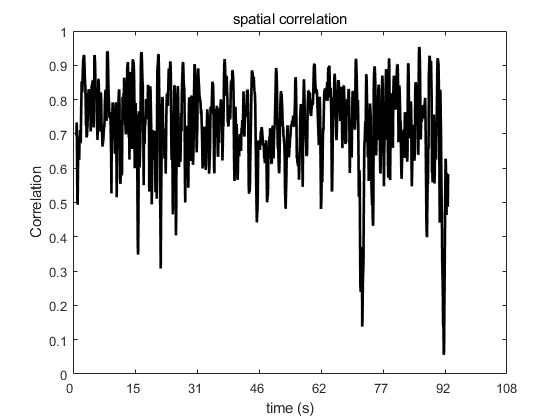


%and the spatial correlation per frame
figure; plot(stats_test.rho_frame,'linewidth',2,'color','k'); title('spatial correlation')
ylabel('Correlation'); set(gca,'xticklabel',round(get(gca,'xtick')/13,0)); xlabel('time (s)');

**That wraps it up for part one. Hopefully this helps get you started using seqNMF to find spatiotemporal motifs in your own data. Good luck! I am always interested in hearing other's results - many of these patterns we observe are reported in the literature in various context (different genotypes, task vs no task, anesthetisia vs no anesthesia, etc.) but I think there is a lot to be learn by direct comparison of motifs discovered across labs, experiments, genotypes, etc. Let's solve the dynamics of the cortex together! **